# 1.1 Механика частиц

#### [Законы Ньютона](https://ru.wikipedia.org/wiki/Законы_Ньютона)

1. Закон инерции

2. Закон ускорения


$$\frac{\textrm{d}}{\textrm{d}t}\left(m\;\mathit{\mathbf{v}}\right)=\mathit{\mathbf{F}}$$


clear
syms t m v(t) F
diff(m*v)==F

$$ans(t) = m\,\frac{\partial }{\partial t}v\left(t\right)=F$$

3. Закон действия и противодействия

#### Постоянное ускорение

syms v v0 a t s
v==v0+a*t

$$ans = v=v_{0}+a\,t$$

s==v0*t+1/2*a*t^2

$$ans = s=\frac{a\,t^{2}}{2}+v_{0}\,t$$

v^2-v0^2==2*a*s

$$ans = v^{2}-{v_{0}}^{2}=2\,a\,s$$

#### Метательная баллистика

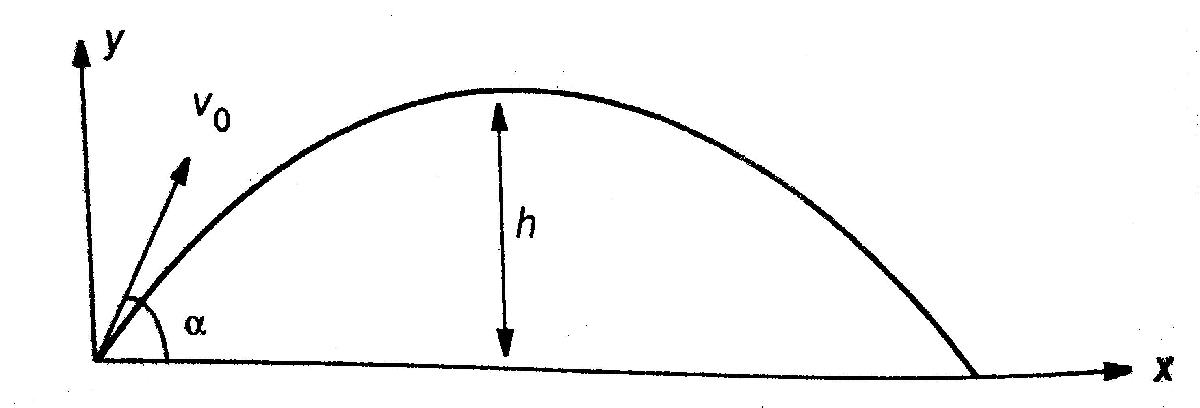


$$\mathit{\mathbf{v}}=v_{0\;} \mathrm{cos}\;\alpha \;\hat{\mathit{\mathbf{x}}} +\left(v_0 \;\mathrm{sin}\;\alpha -g\;t\right)\hat{\mathit{\mathbf{y}}}$$


clear
syms x y t v_x v_y v v0 alpha g t h
[v_x v_y]==[v0*cos(alpha) v0*sin(alpha)-g*t]

$$ans = \left(\begin{array}{cc} v_{x}=v_{0}\,\cos\left(\alpha \right) & v_{y}=v_{0}\,\sin\left(\alpha \right)-g\,t \end{array}\right)$$

v^2==v0^2-2*g*y

$$ans = v^{2}={v_{0}}^{2}-2\,g\,y$$

y==x*tan(alpha)-g*x^2/(2*v0^2*cos(alpha)^2)

$$ans = y=x\,\tan\left(\alpha \right)-\frac{g\,x^{2}}{2\,{v_{0}}^{2}\,{\cos\left(\alpha \right)}^{2}}$$

h==v0^2/(2*g)*sin(alpha)^2

$$ans = h=\frac{{v_{0}}^{2}\,{\sin\left(\alpha \right)}^{2}}{2\,g}$$

#### Количество движения и [импульс](https://ru.wikipedia.org/wiki/Импульс)


$$\mathit{\mathbf{p}}=m\;\mathit{\mathbf{v}}$$


clear
syms p m v S p1 p2 t t1 t2 F(t)
p==m*v

$$ans = p=m\,v$$


$$\mathit{\mathbf{S}}={\mathit{\mathbf{p}}}_2 -{\mathit{\mathbf{p}}}_1 =\int_{t_1 }^{t_2 } \mathit{\mathbf{F}}\;\mathrm{dt}$$


S==p2-p1==int(F,t,t1,t2)

$$ans = \left(S=p_{2}-p_{1}\right)=\int_{t_{1}}^{t_{2}}F\left(t\right)\mathrm{d}t$$

#### [Работа](https://ru.wikipedia.org/wiki/Механическая_работа)


$$W=\int \mathit{\mathbf{F}}\cdot \mathbf{dr}$$


syms W F(r) r 
W==int(F,r)

$$ans(r) = W=\int F\left(r\right)\mathrm{d}r$$


$$W_2 -W_1 =\int_{t_1 }^{t_2 } \mathit{\mathbf{F}}\cdot \mathit{\mathbf{v}}\;\mathrm{dt}=\int_{t_1 }^{t_2 } \mathit{\mathbf{F}}\cdot \mathbf{dr}$$


syms W1 W2 t F(t) v
W2-W1==int(F(t)*v,t,t1,t2)==int(F(r),r)

$$ans = \left(W_{2}-W_{1}=\int_{t_{1}}^{t_{2}}v\,F\left(t\right)\mathrm{d}t\right)=\int F\left(r\right)\mathrm{d}r$$

#### [Кинетическая энергия](https://ru.wikipedia.org/wiki/Кинетическая_энергия)

syms E_k m v
E_k==1/2*m*v^2

$$ans = E_{k}=\frac{m\,v^{2}}{2}$$

#### [Консервативная сила](https://ru.wikipedia.org/wiki/Консервативные_силы)


$$\mathrm{curl}\;\mathit{\mathbf{F}}=\nabla \times \mathit{\mathbf{F}}=0$$


syms rot(X) grad(X) F E_p
rot(F)==0

$$ans = \mathrm{rot}\left(F\right)=0$$


$$F=-\mathrm{grad}\;E_p =-\nabla E_p$$


F==-grad(E_p)

$$ans = F=-\mathrm{grad}\left(E_{p}\right)$$

#### [Закон сохранения энергии](https://ru.wikipedia.org/wiki/Закон_сохранения_энергии) (механической энергии)

syms E E_p E_k
E==E_p+E_k

$$ans = \text{E}=E_{k}+E_{p}$$

#### [Мощность](https://ru.wikipedia.org/wiki/Мощность)


$$P=\mathit{\mathbf{F}}\cdot \mathit{\mathbf{v}}=\frac{d}{\textrm{d}t}W$$


syms P F v W(t) t sprod(x,y)
P==sprod(F,v)==diff(W)

$$ans(t) = \left(P=\mathrm{sprod}\left(F,v\right)\right)=\frac{\partial }{\partial t}W\left(t\right)$$

#### [Угловой момент](https://ru.wikipedia.org/wiki/Момент_импульса)


$$\mathit{\mathbf{L}}=\mathit{\mathbf{r}}\times \mathit{\mathbf{p}}$$


syms vprod(x,y) r p L
L==vprod(r,p)

$$ans = L=\mathrm{vprod}\left(r,p\right)$$

#### [Вращающий момент](https://ru.wikipedia.org/wiki/Момент_силы) (момент силы)

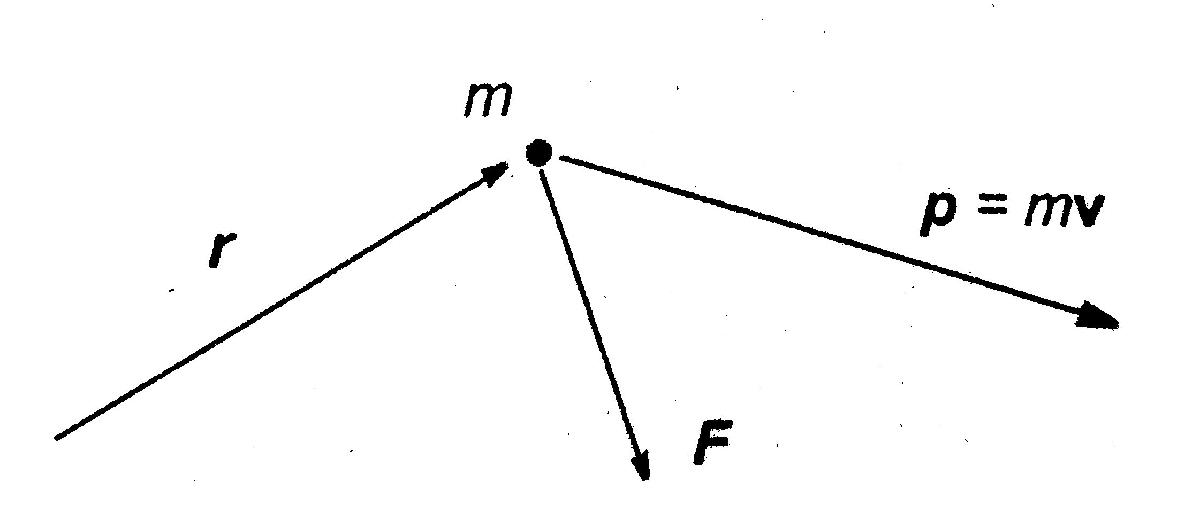


$$\mathit{\mathbf{M}}=\mathit{\mathbf{r}}\times \mathit{\mathbf{F}}$$


syms M r F
M==vprod(r,F)

$$ans = M=\mathrm{vprod}\left(r,F\right)$$

#### Закон моментов (второй закон Эйлера)


$$\frac{\textrm{d}}{\textrm{d}t}{\mathit{\mathbf{L}}}^p ={\mathit{\mathbf{M}}}^p$$


syms t L_p(t) M_p
diff(L_p)==M_p

$$ans(t) = \frac{\partial }{\partial t}L_{p}\left(t\right)=M_{p}$$